# Video Pre-Processing Workflow - Test Concept

**Summary**: 

Initial test of pre-processing workflow. Results used to choose a series of default parameters for subsequent codes. 

**User notes: **

This script is based on the video: **SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi** , 

along with the corresponding folder of extracted frames: **AllFrames_0016 **

If you would like to run the script, please ensure the video and the folder are in the same directory as this script. Link to the files can be found on github. 

**Log:**

13-Dec-2020; SWC. Completed background generation and background subtraction sections. 

14-Dec-2020; SWC. Completed tresholding/binarization sections. Managed to extract bounding boxes. 

02-Feb-2021; SWC. Review script and notes; initial commit to github.

clear all
close all 
clc 

## 1) Load video

vid = VideoReader('SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'); % read video
totframes = vid.NumFrames %check total num of frames in video

totframes = 1434

% frame_width = vid.Width;
% frame_height = vid.Height;

## 2) Background generation

n = 200;    % number of frames to use for background generation 
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

###     a) Mean 

tic
avg_pix = mean(frameMat,3);
toc

Elapsed time is 0.591188 seconds.


###     b) Min

tic
min_pix = min(frameMat,[],3);
toc

Elapsed time is 0.427360 seconds.


###     c) Max

tic
max_pix = max(frameMat,[],3);
toc

Elapsed time is 0.408397 seconds.


###     d) Mode 

tic
mod_pix = mode(frameMat,3);
toc

Elapsed time is 54.157760 seconds.


###     e) Median

tic
med_pix = median(frameMat,3);
toc

Elapsed time is 7.410133 seconds.


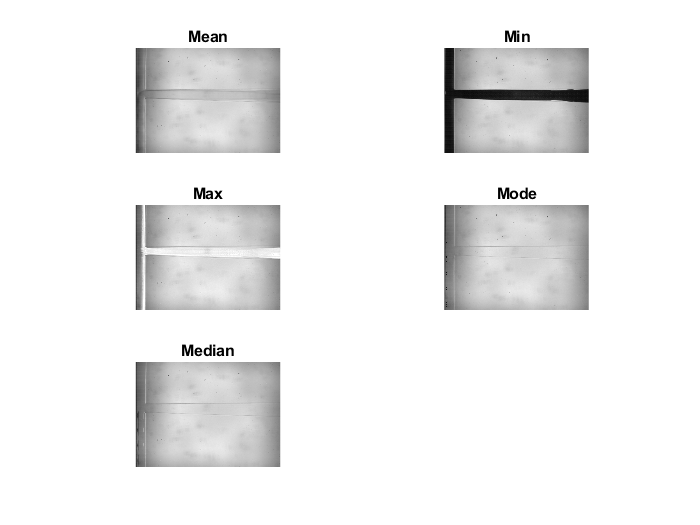


% plot images
subplot(3,2,1); imshow(uint8(avg_pix)); title("Mean")
subplot(3,2,2); imshow(uint8(min_pix)); title("Min")
subplot(3,2,3); imshow(uint8(max_pix)); title("Max")
subplot(3,2,4); imshow(uint8(mod_pix)); title("Mode")
subplot(3,2,5); imshow(uint8(med_pix)); title("Median")

## 3) Background subtraction

In order to evaluate the most suitable background subtraction method, will try on dummy images extracted from video.

By inspection, background generated using 'mode' or 'median' gave the best results. In this section, will use 'median' (computes faster)

**Note: to extract video frames as individual images, use *****extractVidFrames. *****For this video, all video frames have been extracted and saved in folder "AllFrames_0016" in shared drive. Coalescence event occured between frames 1360-1363.**

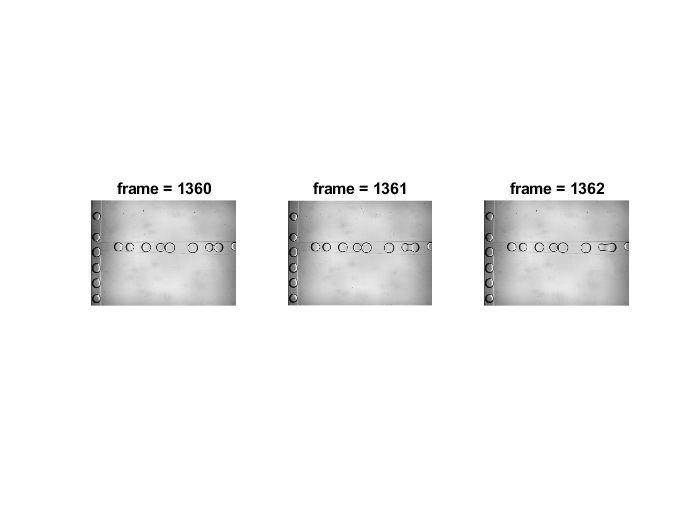

dummy1 = imread("AllFrames_0016\1360.jpg");
dummy2 = imread("AllFrames_0016\1361.jpg");
dummy3 = imread("AllFrames_0016\1362.jpg");

% check images loaded correctly
figure
subplot(1,3,1); imshow(dummy1); title("frame = 1360")
subplot(1,3,2); imshow(dummy2); title("frame = 1361")
subplot(1,3,3); imshow(dummy3); title("frame = 1362")

###     a) Absolute difference

absDiff1 = abs(dummy1-med_pix); 
absDiff2 = abs(dummy2-med_pix); 
absDiff3 = abs(dummy3-med_pix); 


###     b) Standard difference

stdDiff1 = med_pix - dummy1; 
stdDiff2 = med_pix - dummy2;
stdDiff3 = med_pix - dummy3;

###     c) Inverted difference

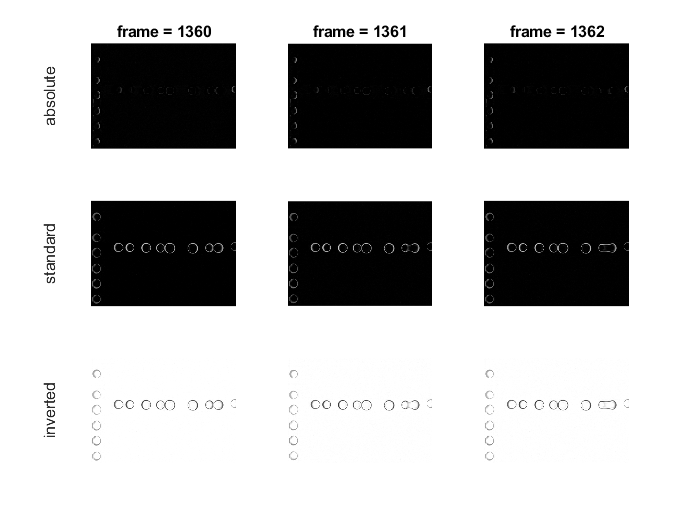

invDiff1 = 255-(med_pix - dummy1); 
invDiff2 = 255-(med_pix - dummy2);
invDiff3 = 255-(med_pix - dummy3);

% plot results
figure 
subplot(3,3,1); imshow(absDiff1); title("frame = 1360"); ylabel("absolute")
subplot(3,3,2); imshow(absDiff2); title("frame = 1361")
subplot(3,3,3); imshow(absDiff3); title("frame = 1362")

subplot(3,3,4); imshow(stdDiff1); ylabel("standard")
subplot(3,3,5); imshow(stdDiff2); 
subplot(3,3,6); imshow(stdDiff3); 

subplot(3,3,7); imshow(invDiff1); ylabel("inverted")
subplot(3,3,8); imshow(invDiff2); 
subplot(3,3,9); imshow(invDiff3); 

## 4) Tresholding & Binarization 

'standard difference' subtraction method seems to give the best results. 

As preliminary step, use global intensity treshold, evaluated at different values:

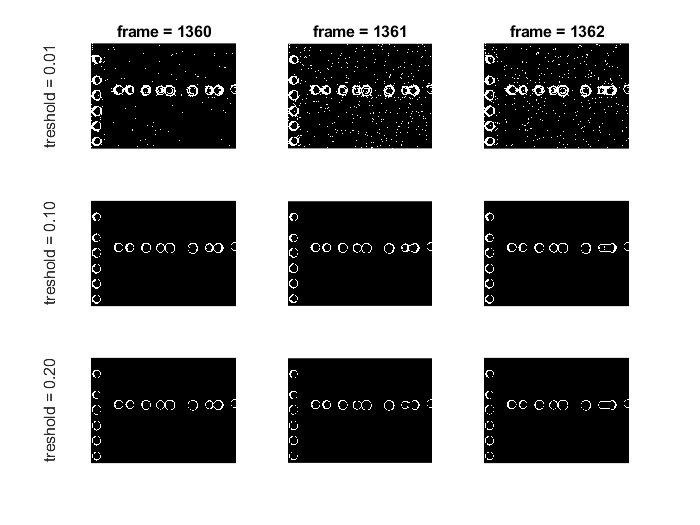

t = 0.01; %treshold value
bin1 = imbinarize(stdDiff1,t);
bin2 = imbinarize(stdDiff2,t);
bin3 = imbinarize(stdDiff3,t);

figure
subplot(3,3,1); imshow(bin1); title("frame = 1360"); ylabel(sprintf("treshold = %0.2f",t))
subplot(3,3,2); imshow(bin2); title("frame = 1361")
subplot(3,3,3); imshow(bin3); title("frame = 1362")

t = 0.1; %treshold value
bin1 = imbinarize(stdDiff1,t);
bin2 = imbinarize(stdDiff2,t);
bin3 = imbinarize(stdDiff3,t);

subplot(3,3,4); imshow(bin1); ylabel(sprintf("treshold = %0.2f",t))
subplot(3,3,5); imshow(bin2); 
subplot(3,3,6); imshow(bin3); 

t = 0.2; %treshold value
bin1 = imbinarize(stdDiff1,t);
bin2 = imbinarize(stdDiff2,t);
bin3 = imbinarize(stdDiff3,t);

subplot(3,3,7); imshow(bin1); ylabel(sprintf("treshold = %0.2f",t))
subplot(3,3,8); imshow(bin2); 
subplot(3,3,9); imshow(bin3); 

Note: have done (bkground - Img) instead of subtracting background from img.. 

## 5) Morphological close and fill

**Run 1**: after intensity tresholding, some blobs have discontinued edges.

**Approach 1**: first perform morphological close, then can use *imfill('holes') / bwconvhull('objects')* to fill all the closed shapes

**Comments:**

- For morphological close action to work well, need brush size larger than hole gap, but should not be larger than distance between drops, otherwise a bridge between drops will form and thus distort the image. 

- One way around this - use a lower intensity treshold to ensure no discontinuity in drop boundary. This is likely to give a more 'noisy' image (e.g. contour regions are kept), but since these noise are within the drop area and we are only concerned about how well the drop edges can be detected, this should be okay for this specific application.

- ***imfill*** - retains shape of drops but unable to detect drops that are not fully bounded (e.g. partial appearance of drops at the border of frame)

- ***bwconvhull*** - provided continuous edge, can detect all drops even those at the frame border. However, shapes are distorted (dilated) - doublets and coasleced drops become virtually the same. However, if ultimate goal is just to identify bounding box, this shouldn't be a problem (shown later).  

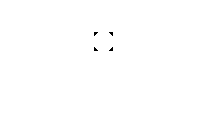

% create image used for testing in this section
Img = imbinarize(stdDiff2,0.3);


SE = strel('disk',10,4); %create structuring element. 
% the specified shape creates a 'round' brush, but could also use other
% shapes (e.g. line, diamond, rectangle)

figure; imshow(SE.Neighborhood) %visualise morphological structuring element

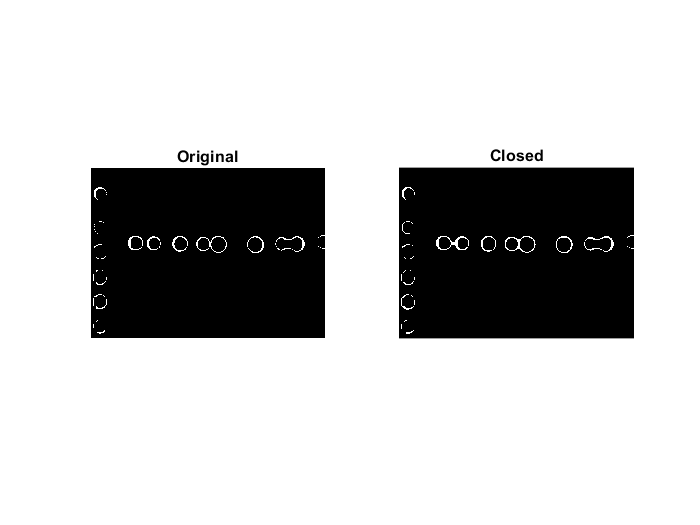

% just use one image as demo
CImg = imclose(Img,SE); 
figure; %display results
subplot(1,2,1); imshow(Img); title('Original')
subplot(1,2,2); imshow(CImg); title('Closed')

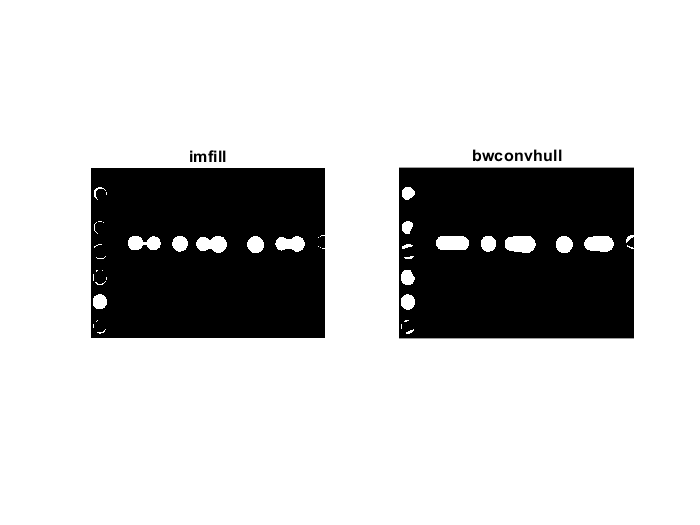


FImg_imfill = imfill(CImg,'holes');
FImg_bwconvhull = bwconvhull(CImg,'objects');
figure; 
subplot(1,2,1); imshow(FImg_imfill); title('imfill')
subplot(1,2,2); imshow(FImg_bwconvhull); title('bwconvhull')

**Run 2:** use a reasonably low treshold value so no gaps in drop boundary (possible in this example, but need to see if feasible for different videos). 

**Approach 2: **No morphological close processing step required. Directly fill image and then extract information on centroid and bounding box.

Will loop this to demonstrate on 3 frames throughout coalescence event. 

**Comments: **successfully extracted bounding box and plotted on original images. Though, as seen in the vertical channels, drop detection is not accurate because their boundaries were disconnected after tresholding. So, need to make sure this is not a problem when implementing in practice.   

*(Update 02-Feb, SWC: This is OK, as we are only interested in drops along main flow channel. Subsequent scripts have included code to only focus on detecting drops in main flow channel)*

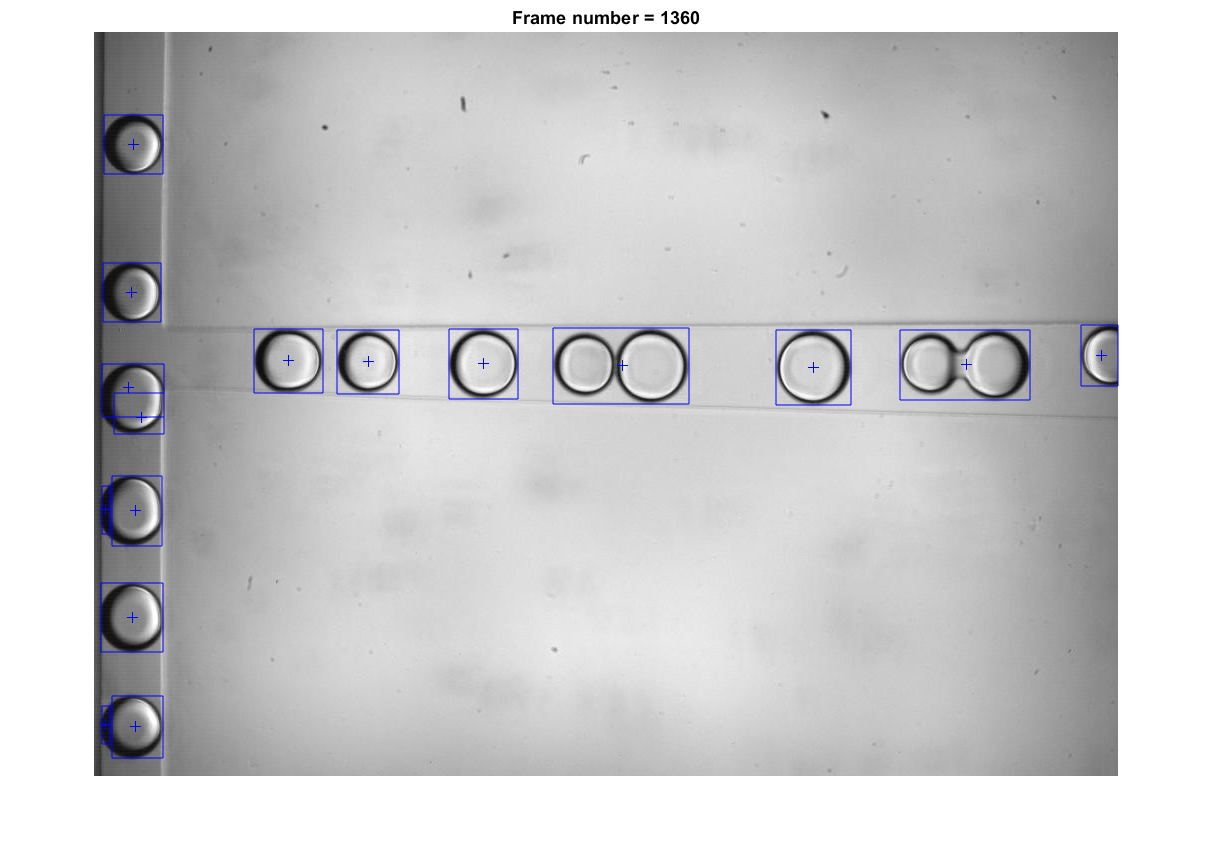

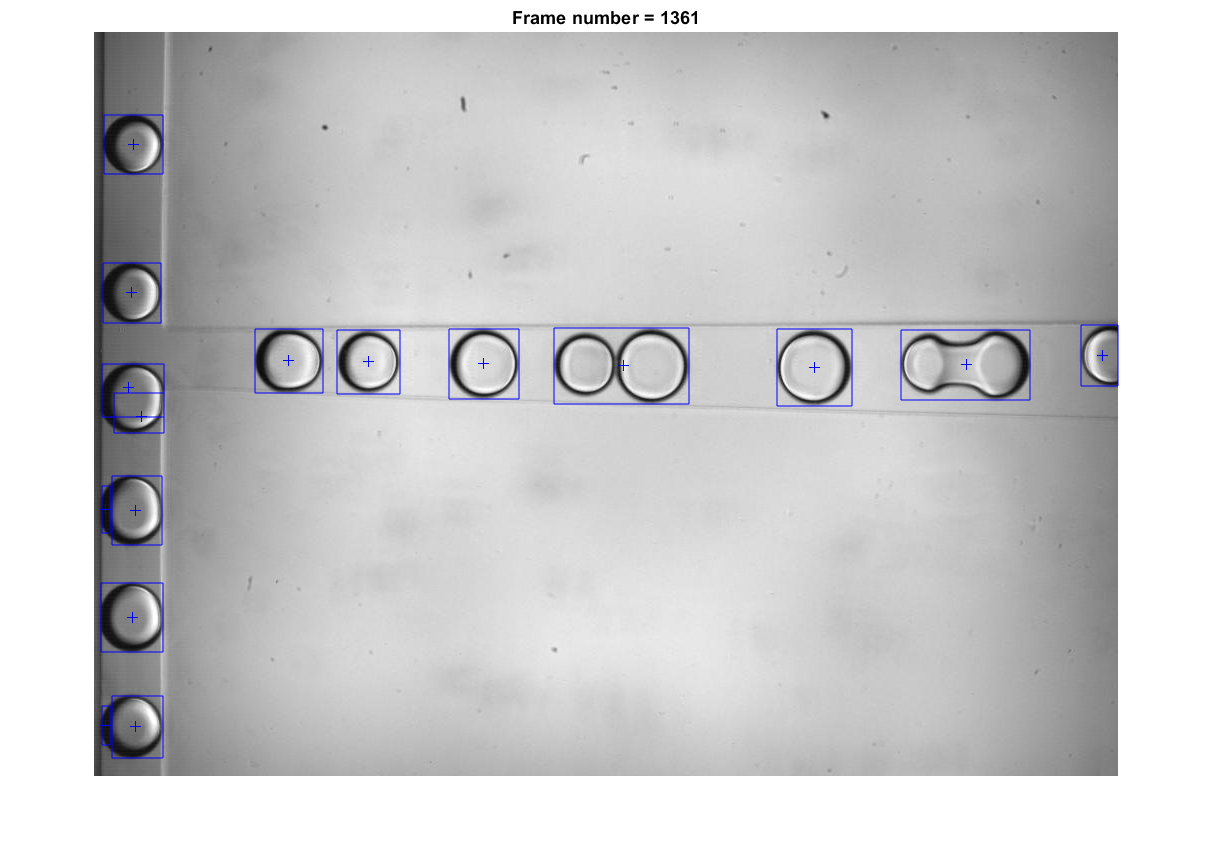

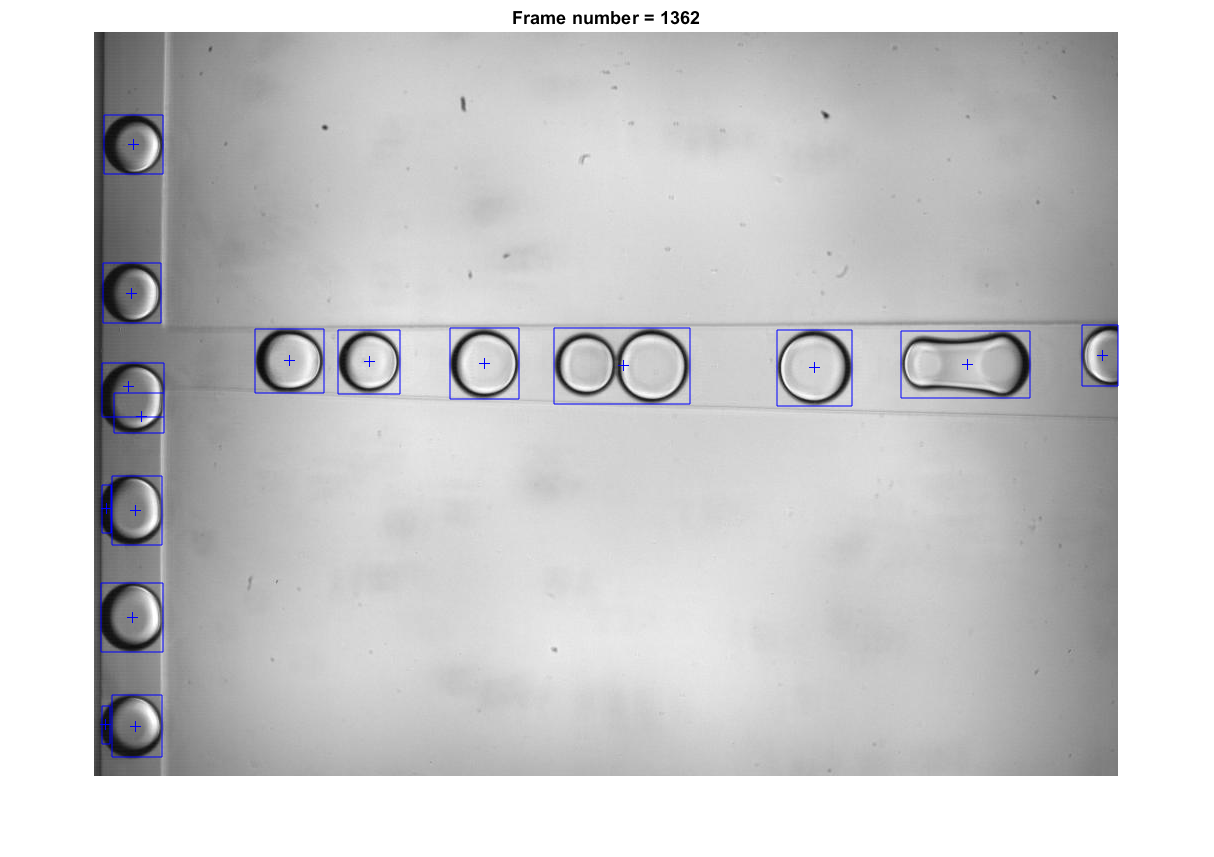

% use images generated in section 4: bin1, bin2, bin3 
ori_mat = cat(3, dummy1, dummy2, dummy3); %matrix of original images
bin_mat = cat(3, bin1, bin2, bin3); %matrix of binarized images
fnum_mat = [1360 1361 1362];

for i = 1:3
    % get image
    I = bin_mat(:,:,i); 
    % fill shapes
    I_Filled = bwconvhull(I,'objects');
    
    % detect regions of interest
    I_roi = regionprops(I_Filled,'centroid','BoundingBox'); %get stats on centroids and bounding box
    centroids = cat(1,I_roi.Centroid);
    box = cat(1,I_roi.BoundingBox);
    
    % load original frame 
    figure 
    imshow(ori_mat(:,:,i)); 
    title(sprintf('Frame number = %d', fnum_mat(i)))
    hold on 
    
    % display bounding boxes on orginal frames
    plot(centroids(:,1), centroids(:,2),'b+')
        
    for i=1:length(box)
        rectangle('Position',box(i,:),'EdgeColor','b')
    end
    
end

**Next Questions**: 

- to retain orginal dimensions of bounding boxes, or further process to make all bounding boxes into uniform dimension (meaning cropped image do not need to be resized before feeding to classifier).  ----- *(Update 02-Feb, SWC: subsequent scripts have been written so cropped images are uniform 128x128 pix^2)*

- does this work just as well with drops in different orientation? ----- *(Update 02-Feb, SWC: yes, drop orientation does not matter, more important is the imaging quality - to ensure the default (fixed) tresholding value is suitable)*